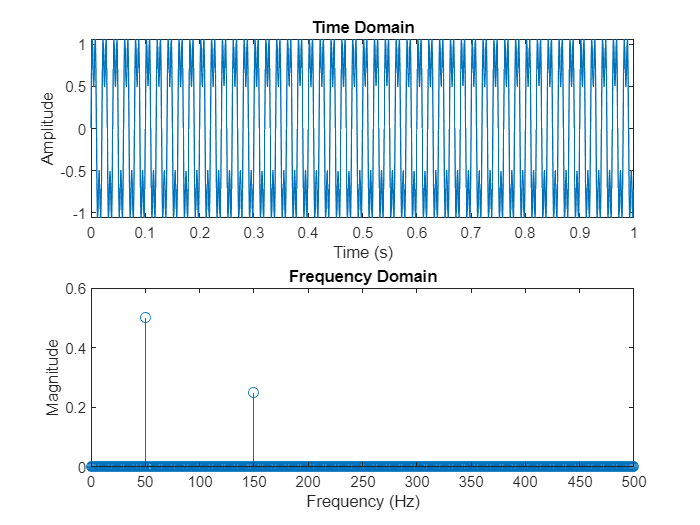

% Generate a harmonic signal
frequency = 50; % Fundamental frequency in Hz
amplitude = 1; % Amplitude of the fundamental component
harmonicFrequency = 150; % Frequency of the harmonic component in Hz
harmonicAmplitude = 0.5; % Amplitude of the harmonic component
samplingRate = 1000; % Sampling rate in samples per second
duration = 1; % Duration of the signal in seconds

t = 0:1/samplingRate:duration-1/samplingRate; % Time vector
signal = amplitude*sin(2*pi*frequency*t) + harmonicAmplitude*sin(2*pi*harmonicFrequency*t);

% Perform Fourier analysis
N = length(signal); % Number of samples
fftSignal = fft(signal); % Compute the discrete Fourier transform
frequencies = (0:N-1)*(samplingRate/N); % Frequency axis

% Plot the original signal
subplot(2,1,1);
plot(t, signal);
title('Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the Fourier spectrum
subplot(2,1,2);
stem(frequencies, abs(fftSignal)/N);
title('Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Set x-axis limits for better visualization
xlim([0 samplingRate/2]);


% Display the dominant frequencies and their magnitudes
[sortedMagnitudes, sortedIndices] = sort(abs(fftSignal)/N, 'descend');
dominantFrequencies = frequencies(sortedIndices(1:5));
dominantMagnitudes = sortedMagnitudes(1:5);
disp('Dominant Frequencies:');

Dominant Frequencies:


disp(dominantFrequencies);

    50   950   150   850   149



disp('Corresponding Magnitudes:');

Corresponding Magnitudes:


disp(dominantMagnitudes);

    0.5000    0.5000    0.2500    0.2500    0.0000

